- Fit a cubic polynomial to the following data by extending the system of equations on lecture slide 3, then calculate the standard error and correlation coefficient. Graph the data and your fitting equation.

q1()

    0.0467   -1.0412    7.1438  -11.4887



2. Do the same as in the Question 1 but using the general Z-matrix formulation given on slides 21-25. You should get the same result if you have done it correctly.

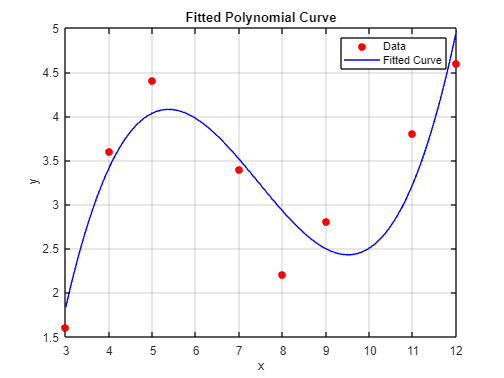

Standard Error: 0.570031
Correlation Coefficient (R-squared): 0.910484


q2()

3. Calculate the standard error for the 2 power equation models from Example 6 in the lecture notes and decide if one equation is better than the other or not.

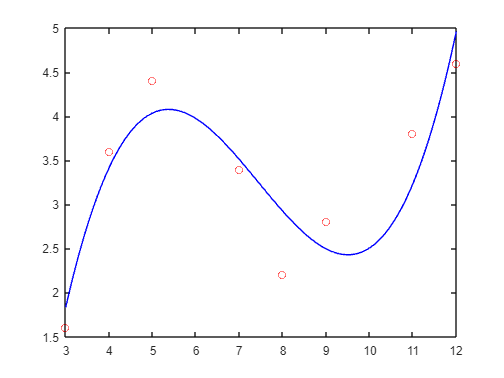

Standard Error (Linear): 240.039439
Standard Error (Nonlinear): 192.615700


q3()

4. For the following data use polynomial regression to get an equation that predicts the dissolved oxygen concentration as a function of temperature for the case where the chloride concentration is 0. Graph the data and your fitting equation.

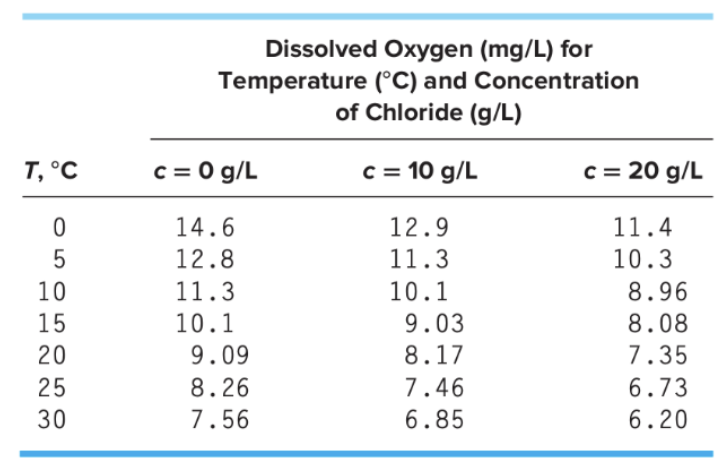

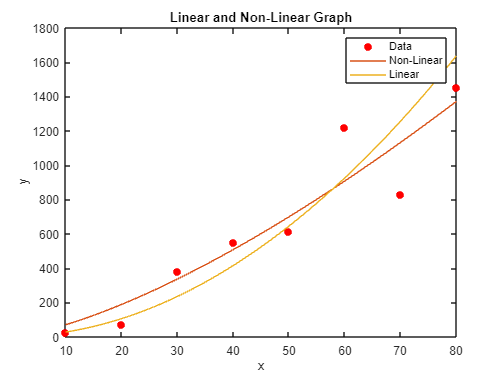

--------------------- Q4 ----------------------
    0.0044   -0.3634   14.5519



q4()

5. For the data from Question 4 use multiple linear regression to predict the dissolved oxygen concentration as a function of temperature and chloride concentration (**Hint: Make a new table of values**). Plot the data and your equation then use your equation to predict the dissolved oxygen concentration when the chloride concentration is 15 g/L and temperature is 12oC.

q5()

--------------------- Q5 ----------------------
Oxygen estimated to be 9.533357


6. Use multiple linear regression to fit the following data. Also calculate the standard error and correlation coefficient.

q6()

--------------------- Q6 ----------------------
a =
   14.4609
    9.0252
   -5.7043

r = 0.997759
Syx = 0.888787


7. Fluid flow was measured in concrete circular pipes of various sizes and angles (slopes). Use multiple linear regression (logarithm method) to fit the following equation to the data.

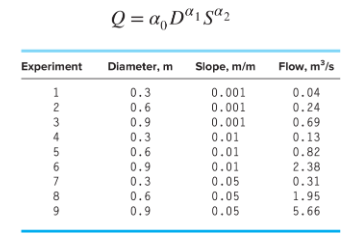

q7()

--------------------- Q7 ----------------------
   36.3813

    2.6279

    0.5320



8. Three disease-carrying organisms decay exponentially in seawater according to the following model equation. Use general least squares to estimate the coefficients and estimate the initial concentration of each organism from the following measurements.

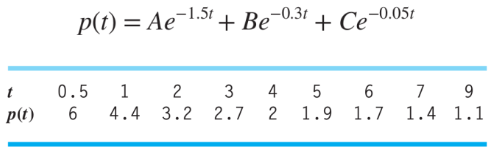

q8()

9. Use nonlinear regression to estimate α4 and β4 based on the following data. Develop a plot of your fit along with the data.

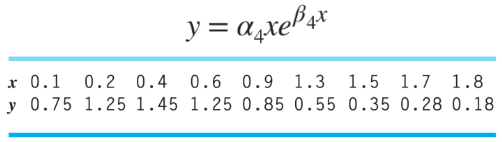

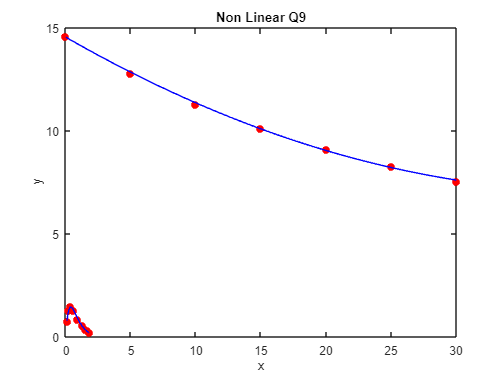

--------------------- Q9 ----------------------
Optimal alpha: 9.8974
Optimal beta: -2.5319


q9()

10. Use Matlab’s symbolic toolbox to factorise the following polynomial:

q10()

$$\left(\begin{array}{ccc} x+3 & x-1 & x+1 \end{array}\right)$$

11. Use Matlab’s symbolic toolbox to find the 3rd order Taylor series expansion of the following function about the point x = –1.

q11()

$$\left(17\,\cos\left(6\right)\,{\mathrm{e}}^{-3}-6\,{\mathrm{e}}^{-3}\,\sin\left(6\right)\right)\,\left(x+1\right)-{\mathrm{e}}^{-3}\,\sin\left(6\right)-{\left(x+1\right)}^{2}\,\left(15\,{\mathrm{e}}^{-3}\,\sin\left(6\right)-102\,\cos\left(6\right)\,{\mathrm{e}}^{-3}+{\mathrm{e}}^{-3}\,\left(26\,\cos\left(6\right)-\frac{289\,\sin\left(6\right)}{2}\right)\right)$$

12. Use Matlab’s symbolic toolbox to solve the following system of equations for the variables x and y.

q12()

x = 29/10
y = -33/10


13. Use Matlab’s symbolic toolbox to differentiate the following function.

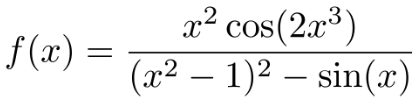

q13()

$$\begin{array}{l} \frac{6\,x^{4}\,\sin\left(2\,x^{3}\right)}{\sigma_{1}}-\frac{2\,x\,\cos\left(2\,x^{3}\right)}{\sigma_{1}}+\frac{x^{2}\,\cos\left(2\,x^{3}\right)\,\left(\cos\left(x\right)-4\,x\,\left(x^{2}-1\right)\right)}{{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(x\right)-{\left(x^{2}-1\right)}^{2} \end{array}$$

14. Use Matlab’s symbolic toolbox to solve the following indefinite integral.

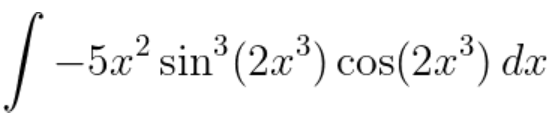

q14()

$$-\frac{5\,{\sin\left(2\,x^{3}\right)}^{4}}{24}$$

15. Convert the antiderivative you found in Question 14 into a Matlab Function and use it to evaluate (using the Fundamental Theorem of Calculus):

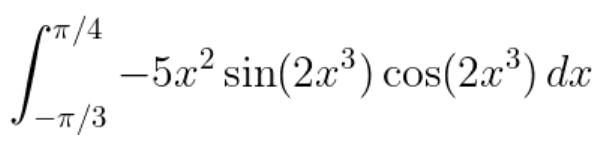

q15()

   -0.0310



function q1()
    x = [3, 4, 5, 7, 8, 9, 11, 12];
    y = [1.6, 3.6, 4.4, 3.4, 2.2, 2.8, 3.8, 4.6];
    n = length(x);

    % Plot the data points
    plot(x, y, 'ro', 'MarkerFaceColor', 'r');

    % Create a higher-resolution range of x values
    mat = [n, sum(x), sum(x.^2), sum(x.^3);
          sum(x), sum(x.^2), sum(x.^3), sum(x.^4);
          sum(x.^2), sum(x.^3), sum(x.^4), sum(x.^5)
          sum(x.^3), sum(x.^4), sum(x.^5), sum(x.^6)];

    r = [sum(y); sum(x.*y); sum(x.^2.*y); sum(x.^3.*y)];

    a = mat \ r;

    %turn matrix into row
    a = a';
    %switch position of matrix
    a = a(:, end:-1:1);
    disp(a)

    % Create a higher-resolution range of x values
    x_range = linspace(min(x), max(x), 100); % Adjust the number of points as needed

    % Evaluate the polynomial on the higher-resolution range
    y_fit = polyval(a, x_range);

    % Plot the fitted curve using the higher-resolution range of x values
    hold on;
    plot(x_range, y_fit, 'b');
    
    xlabel('x');
    ylabel('y');
    title('Fitted Polynomial Curve');
    legend('Data', 'Fitted Curve');
    grid on;
end


function q2()
    hold off
    x = [3, 4, 5, 7, 8, 9, 11, 12]';
    y = [1.6, 3.6, 4.4, 3.4, 2.2, 2.8, 3.8, 4.6]';

    y_mean = sum(y) / length(y);

    % Form the matrix of z and a
    z = [ones(size(x)), x, x.^2, x.^3];
    
    % z matrix formula
    a = ((z' * z) \ (z' * y))';
    a = a(:, end:-1:1);

    % Calculate the sum of squares of residuals
    S_r = sum((y - polyval(a, x)).^2);

    % Calculate the standard error
    deg = 3;
    std_error = sqrt(S_r / (length(x) - (deg + 1)));

    % Calculate the total sum of squares
    S_t = sum((y - y_mean).^2);

    % Calculate the coefficient of determination (R-squared)
    r_square = (S_t - S_r) / S_t;
    r = sqrt(r_square);

    fprintf('Standard Error: %f\n', std_error);
    fprintf('Correlation Coefficient (R-squared): %f\n', r);

    x_range = linspace(min(x), max(x), 100);
    y_fit = polyval(a, x_range);
    plot(x, y, 'ro');
    hold on;
    plot(x_range, y_fit, 'b');
end


function q3()
    hold off
    x = [10; 20; 30; 40; 50; 60; 70; 80];
    y = [25; 70; 380; 550; 610; 1220; 830; 1450];
    logX = log(x);
    logY = log(y);

    %Find a of linear
    Z = [ones(size(x)) logX];
    logA = (Z'*Z)\(Z'*logY);
    a = exp(logA);
    a(2) = log(a(2));

    % Use fminsearch to find the values of parameters A (alpha and beta)
    A = fminsearch(@fit_power, [1, 1], [], x, y);
    
    % Define a function F for the fitted nonlinear model
    NL = @(x) A(1) * x.^(A(2));
    L = @(x) a(1)* x.^(a(2));

    % Calculate the degrees of freedom (n - number of parameters)
    df_linear = length(x) - 2;  % 2 parameters for linear fit a(1), a(2)
    df_nonlinear = length(x) - 2;  % 2 parameters for nonlinear fit A(1), A(2)

    % Calculate the sum of squared residuals for the linear fit
    residuals_linear = y - L(x);
    S_r_linear = sum(residuals_linear.^2);

    % Calculate the sum of squared residuals for the nonlinear fit
    residuals_nonlinear = y - NL(x);
    S_r_nonlinear = sum(residuals_nonlinear.^2);

    % Calculate the standard errors for linear and nonlinear fits
    std_error_linear = sqrt(S_r_linear / df_linear);
    std_error_nonlinear = sqrt(S_r_nonlinear / df_nonlinear);

    plot(x, y, 'or', 'Markersize', 6, 'Markerfacecolor', 'r');
    hold on
    fplot(NL, [10, 80]);
    fplot(L, [10, 80]);
    legend('Data', 'Non-Linear', 'Linear');
    title('Linear and Non-Linear Graph')
    xlabel('x')
    ylabel('y')

    % Print the standard errors
    fprintf('Standard Error (Linear): %f\n', std_error_linear);
    fprintf('Standard Error (Nonlinear): %f\n', std_error_nonlinear);

    % Nested function to calculate the sum of squared residuals
    function Sr = fit_power(a, x_data, y_data)
        % a = [alpha, beta]
        % Calculate the fitted values based on the current parameters
        F_power = a(1) * x_data.^a(2);
        % Calculate the sum of squared residuals
        Sr = sum((y_data - F_power).^2);
    end
end


function q4()
    hold off
    disp('--------------------- Q4 ----------------------')
    T = 0:5:30;
    c0 = [14.6, 12.8, 11.3, 10.1, 9.09, 8.26, 7.56];
    
    plot(T, c0, 'ro', MarkerFaceColor='r')
    a = polyfit(T, c0, 2);
    disp(a)
    hold on
    Trange = linspace(min(T), max(T), 100);
    y_fit = polyval(a, Trange);
    plot(Trange, y_fit, 'b');
end

function q5()
    disp('--------------------- Q5 ----------------------')
    % Step 1: Domain
    tval = 0:5:30;
    t = [tval, tval, tval]';
    c = repelem([0, 10, 20], 7)';
    % c = [0 0 0 0 0 0 0 10 10 10 10 10 10 10 20 20 20 20 20 20 20]';
    y = [14.6 12.8 11.3 10.1 9.09 8.26 7.56 12.9 11.3 10.1 9.03 8.17 7.46 6.85 11.4 10.3 8.96 8.08 7.35 6.73 6.20]';
    
    % Step 2: Solve for a to create fitted function
    z = [ones(size(t)), t, c];  % เป็น 2 ตัวแปร
    a = (z'*z)\(z'*y);
    
    % Step 3: Create fitted function
    fitted_func = @(temp, concent) a(1) + a(2).*temp + a(3).*concent;
    
    % Step 4: Eval the value
    fprintf('Oxygen estimated to be %f\n', fitted_func(12, 15));
end

function q6()
    disp('--------------------- Q6 ----------------------')
    % Step 1: Domain
    x1 = [0 1 1 2 2 3 3 4 4]';
    x2 = [0 1 2 1 2 1 2 1 2]';
    y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2]';
    n = length(x1);
    degree = 2;
    
    % Step 2: Create fitted function
    z = [ones(size(x1)) x1 x2];  % เป็น 2 ตัวแปร
    a = (z'*z)\(z'*y);
    disp('a =');
    disp(a);
    
    % Step 3: Calculate Std.Err and Correlation Coef.
    
    % Correlation Coef. => r.^2 = st - sr / st
    ybar = mean(y);
    st = sum((y - ybar).^2);
    sr =  sum((y - a(1) - a(2).*x1 - a(3).*x2).^2);
    r2 = sqrt((st - sr) ./ st);
    
    % Standard Error => sqrt( sr / n - (m+1) )
    % n = number of data points
    % m = degree of a polynomial
    syx = sqrt(sr ./ (n - (degree + 1)));
    fprintf("r = %f\n", r2);
    fprintf("Syx = %f\n", syx);
end

function q7()
    disp('--------------------- Q7 ----------------------')
    % Data
    experiment = 1:1:9;
    d = [0.3, 0.6, 0.9, 0.3, 0.6, 0.9, 0.3, 0.6, 0.9];
    s = [0.001, 0.001, 0.001, 0.01, 0.01, 0.01, 0.05, 0.05, 0.05];
    q = [0.04, 0.24, 0.69, 0.13, 0.82, 2.38, 0.31, 1.95, 5.66];
    
    
    % linearize equation Q = a0 * d^a1 * s^a2 by taking log both side
    % you will get logQ = log(a0) + a1log(d) + a2log(s)

    % Linearise the data อิงจากโจทย์
    % Find log(d), log(s), log(Q)
    logd = log(d);
    logs = log(s);
    logq = log(q);

    % Step 2: Use multiple linear regression to fit
    a = multipleLinearRegression(logd', logs', logq');
    
    % we get logQ = log(a0) + a1log(d) + a2log(s)
    % since log(a0) = 3.5941, solve to find a0 by exp(3.5941)
    a1final = exp(a(1));

    % Step 3: Create eqn.
    func = @(d, s) real_alpha .* d.^a(2) .* s.^a(3);
    
    % Step 4: Test and display
    fprintf('Test function with diameter = 0.3m and slope = 0.001 m/m = %f\n', func(0.3, 0.001));
    fprintf('Qfit = %f*D^%f*S^%f\n', real_alpha, a(2), a(3));
    
    % display answer
    disp(a1final);
    disp(a(2));
    disp(a(3));
end

function q8()
    % Datas
    t = [0.5, 1, 2, 3, 4, 5, 6 ,7 ,9]';
    y = [6, 4.4, 3.2, 2.7, 2, 1.9, 1.7, 1.4, 1.1]';
    
    % zeros(size(t)) is to fill a column with 0 since there is no D where De^t
    % exist, if exist then it should be 1
    % exp(-1.5.*t) is adding e^(-1.5t) etc...
    z = [zeros(size(t)) exp(-1.5.*t) exp(-0.3.*t) exp(-0.05.*t)];
    a = (z'*z)\(z'*y);
end

function q9()
    disp('--------------------- Q9 ----------------------')
    x = [0.1, 0.2, 0.4, 0.6, 0.9, 1.3, 1.5, 1.7, 1.8];
    y = [0.75, 1.25, 1.45, 1.25, 0.85, 0.55, 0.35, 0.28, 0.18];

    % Use fminsearch to fit the power-law model and find alpha, beta
    % [1, 1] is the initial guess, input params
    A = fminsearch(@fit_power, [1, 1]);

    % Display the optimal parameters
    disp(['Optimal alpha: ', num2str(A(1))]);
    disp(['Optimal beta: ', num2str(A(2))]);

    plot(x, y, 'ro', MarkerFaceColor='r')
    hold on
    rangeX = linspace(min(x), max(x), 100);
    rangeY = A(1) .* rangeX .* exp(A(2) .* rangeX);
    plot(rangeX, rangeY, 'b')
    xlabel('x')
    ylabel('y')
    title('Non Linear Q9')

    function sse = fit_power(params)
        a = params(1);
        b = params(2);
        
        % Calculate model predictions using the power-law model
        F_power = a * x .* exp(b * x);

        % Calculate the sum of squared errors
        sse = sum((y - F_power).^2);
    end
end

function q10()
    syms x
    eqn = x^3 + 3*x^2 - x - 3;
    facEqn = factor(eqn);
    disp(facEqn)
end


function q11()
    syms x
    y = exp(-3*x.^2) * sin(x.^7 - 5*x.^2);
    % Find the 3rd order Taylor series expansion around x = -1
    taylor_expansion = taylor(y, x, -1, 'Order', 3);
    disp(taylor_expansion);
end


function q12()
    syms x y
    eqn1 = 3*x - y == 12;
    eqn2 = x + 3 * y == -7;

    % Solve the system of equations
    sol = solve([eqn1, eqn2], [x, y]);
    
    disp(['x = ', char(sol.x)]);
    disp(['y = ', char(sol.y)]);
end


function q13()
    syms x
    y = (x.^2 * cos(2*x^3))/ ((x^2 - 1)^2 - sin(x));

    % Differentiate y with respect to x
    dy_dx = diff(y, x);
    disp(dy_dx)
end

function q14()
    syms x
    eqn = -5*x^2 * sin(2*x^3)^3 * cos(2*x^3);
    disp(int(eqn))
end

function q15()
    syms x;
    eqn = -5*x^2 * sin(2*x^3)^3 * cos(2*x^3);
    intEqn = int(eqn, x, [-pi/3, pi/4]);
    disp(double(intEqn))
    
    % F(x=top(pi/4)) - F(x=bottom(-pi/3))
    
    %Ff = matlabFunction(intEqn);
    %ans=Ff(pi/4)-Ff(-pi/3)
    
    %----integral f(x) -> F(x) -----------------------
    %----integral f(x) from a to b = F(b)- F(a)-------
    
    %-----integral -5*x^2*(sin(2*x^3))^3*cos(2*x^3) from -pi/3 to pi/4---
    %------- = F(pi/4)- F(-pi/3)--------------
end




function err = errorCorr(a, b, eq, no)
% for calculating any polynomials EXCEPT multivariable polynomials
% a is array x, b is array y, eq is syms with var x , y, no is no. of
% polynomials
    
    sr = 0;
    st = 0;

    for m = 1:length(a)
        A = a(m);
        syms x
        sr = sr + (b(m) - (subs(eq, x, A)))^2;
        st = st + (b(m) - mean(b))^2;
    end

    % Finding r2 (r2 = (st - sr)/st)
    r2 = sqrt(1 - (sr/st));

    % Finding synx (syx = sqrt(sr/(n- (m+1))))
    synx = sqrt(sr/(length(b) - (no + 1)));

    % Return both synx, r2
    err = [double(synx), double(r2)];
end

function [coefficients] = multipleLinearRegression(x, y, z)
% remember to flip x, y, and z
    a = [ones(size(x)) x y]; % create matrix of 1s size x
    b = (a'*a)\(a'*z); % find coefficient
    coefficients = b;
end